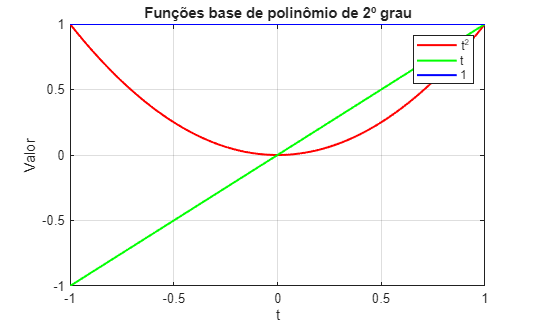

%% Questão 1 - Polinômio de segundo grau

% Intervalo do tempo
t = -1:0.01:1;

% (a) Funções base: t^2, t e 1
base1 = t.^2;
base2 = t;
base3 = ones(size(t));

figure;
plot(t, base1, 'r', 'LineWidth', 1.5); hold on;
plot(t, base2, 'g', 'LineWidth', 1.5);
plot(t, base3, 'b', 'LineWidth', 1.5); grid on;
title('Funções base de polinômio de 2º grau');
xlabel('t'); ylabel('Valor');
legend('t^2','t','1');

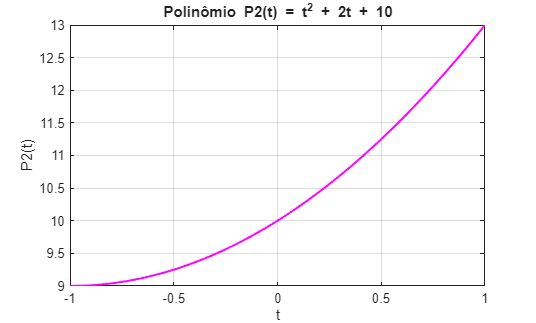


% (b) Polinômio com a=1, b=2, c=10
a = 1; b = 2; c = 10;
P2 = a*t.^2 + b*t + c;

figure;
plot(t, P2, 'm', 'LineWidth', 1.5); grid on;
title('Polinômio P2(t) = t^2 + 2t + 10');
xlabel('t'); ylabel('P2(t)');


%% Questão 2 - Produto escalar

% Definição das funções
g = @(t) 5*t.^2 + 2*t + 9;
h = @(t) sin(2*t).*log(5 + 3*t);

% Produto escalar via integração numérica
produto_escalar = integral(@(t) g(t).*h(t), -1, 1);

% Mostrar resultado
disp(['Produto escalar <g,h> = ', num2str(produto_escalar)]);

Produto escalar <g,h> = 9.2327


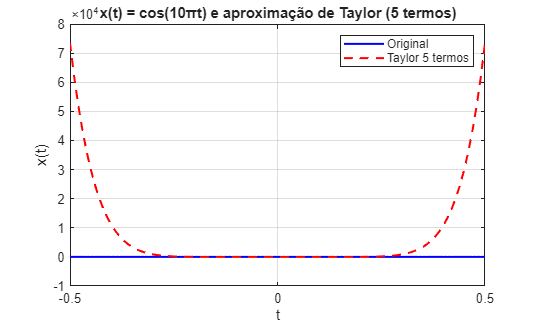


%% Questão 3 - Aproximação por Série de Taylor (sem toolbox)

t = -0.5:0.01:0.5;  % intervalo
x_original = cos(10*pi*t);

% Aproximação de Taylor até 5 termos (ordem 8)
x_aprox = 1 ...
    - (10*pi*t).^2/factorial(2) ...
    + (10*pi*t).^4/factorial(4) ...
    - (10*pi*t).^6/factorial(6) ...
    + (10*pi*t).^8/factorial(8);

% Plotagem
figure;
plot(t, x_original, 'b', 'LineWidth', 1.5); hold on;
plot(t, x_aprox, 'r--', 'LineWidth', 1.5); grid on;
title('x(t) = cos(10πt) e aproximação de Taylor (5 termos)');
xlabel('t'); ylabel('x(t)');
legend('Original','Taylor 5 termos');